clc;clear 
import robo.*

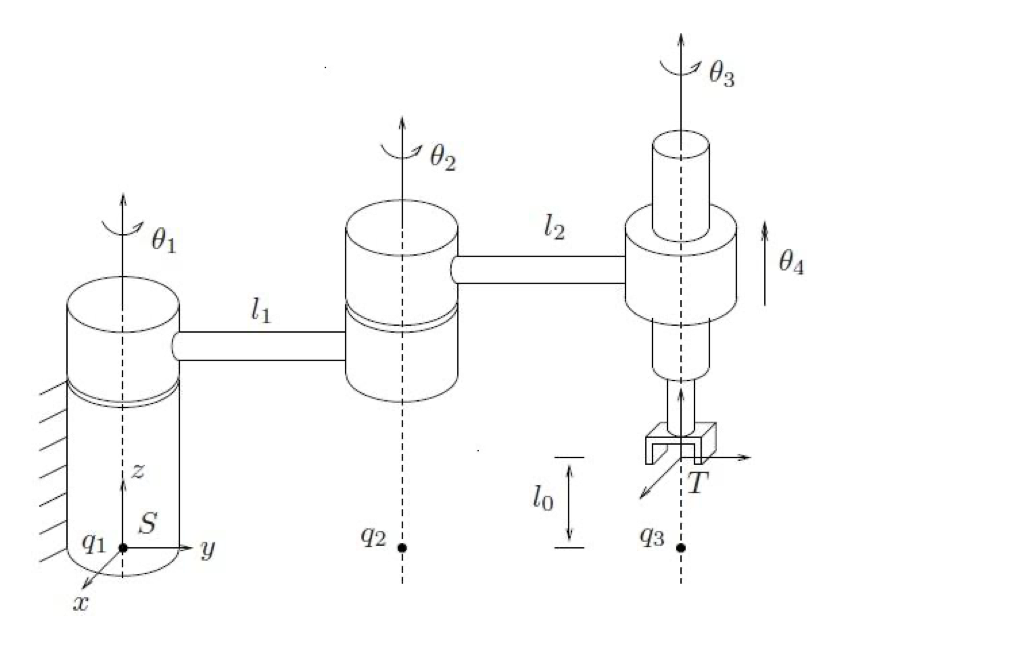

%%Parameter setting
l0   = 0.3; l1 = 1.2 ; l2 = 0.8;
theta = deg2rad([15;54;-32]); theta_dot = [0.4;-0.2;0.28;0.01];
F1 = [100;0;0;0;0;0];
F2 = [0;100;0;0;0;0];
F3 = [0;0;100;0;0;0];
F4 = [0;0;0;100;0;0];
F5 = [0;0;0;0;100;0];
F6 = [0;0;0;0;0;100];
theta(4)= 0.05 %prismatic joint 平移

theta =     0.2618
    0.9425
   -0.5585
    0.0500



% exp methods to generate
w1 = [0;0;1];  q1 = [0;  0;    0];  v1 = -hatm(w1)*q1;  xi1 = [v1; w1];  % Joint 1
w2 = [0;0;1];  q2 = [0;  l1;   0];  v2 = -hatm(w2)*q2;  xi2 = [v2; w2];  % Joint 2
w3 = [0;0;1];  q3 = [0;  l1+l2;0];  v3 = -hatm(w3)*q3;  xi3 = [v3; w3]; % Joint 3

w4 = [0;0;0];                       v4 = [0;  0;   1];  xi4 = [v4; w4];  % Joint 4 平动

% 构建spatial frame的initial坐标
gst0 = [eye(3) [0;l1+l2;l0];
    0 0 0 1];

%===== Calculate Instaneous velocity
G1 = gtwist(xi1, theta(1));
G2 = gtwist(xi2, theta(2));
G3 = gtwist(xi3, theta(3));
G4 = gtwist(xi4, theta(4));


gst = G1 * G2 * G3 * G4 * gst0;
gst_i = inv(gst);



## ====== Part 1: 空间速度 V^s (MLS eq. 3.52/3.54) ======

% 累积 g_{s,i-1} (用于空间 Jacobian, MLS eq. 3.54)
g_s0 = eye(4);        % 关节 1 之前 = I
g_s1 = G1;            % 关节 2 之前
g_s2 = G1 * G2;       % 关节 3 之前
g_s3 = G1 * G2 * G3;  % 关节 4 之前
%  J^s_i = Ad_{g_{s,i-1}} · ξ_i (课件 May_11, eq. 3.54)

Js = zeros(6, 4);
Js(:,1) = adjoint(g_s0) * xi1;      % g_s0 = I
Js(:,2) = adjoint(g_s1) * xi2;
Js(:,3) = adjoint(g_s2) * xi3;
Js(:,4) = adjoint(g_s3) * xi4;

Vs = Js * theta_dot;                % V^s = J^s ·  θ_dot

%% 

## ===== Body Jacobian (MLS eq. 3.55, via Ad^{-1} relation) ====

%  J^b = Ad_{gst}^{-1} · J^s
Jb = adjoint(inv(gst)) * Js;


##  ====== Part 2: 物体速度 V^b (MLS eq. 2.61) ======

%  V^b = Ad_{gst}^{-1} · V^s
Vb = adjoint(inv(gst)) * Vs;

vb = Vb(1:3)

vb =    -0.5807
    0.0950
    0.0100


wb = Vb(4:6)

wb =          0
         0
    0.4800


%% 

## ====== Part 3: 关节力矩 τ = (J^b)^T F^b (MLS eq. 3.59) ======

% 6×6 单位矩阵 = 6 种单位基力旋量 (体坐标系)
Fb_cases = eye(6);
labels   = {'f_x=1','f_y=1','f_z=1','τ_x=1','τ_y=1','τ_z=1'};

fprintf('\n===== Part 3: 关节力矩 τ = (J^b)^T · F^b =====\n');


===== Part 3: 关节力矩 τ = (J^b)^T · F^b =====


fprintf('  %-8s %10s %10s %10s %10s\n', 'F^b 载荷','τ_1','τ_2','τ_3','τ_4');

  F^b 载荷          τ_1        τ_2        τ_3        τ_4


tau1 = Jb' * F1;
tau2 = Jb' * F2;
tau3 = Jb' * F3;
tau4 = Jb' * F4;
tau5 = Jb' * F5;
tau6 = Jb' * F6;
% tau_Fb = zeros(4, 6);
% for k = 1:6
%     tau_Fb(:,k) = Jb' * Fb_cases(:,k);
%     fprintf('  %-8s %10.4f %10.4f %10.4f %10.4f\n', labels{k}, tau_Fb(:,k));
% end
%%

##  ====== Part 4: 空间力旋量 F^s (MLS eq. 2.67 力旋量变换) ======

%  F^b = Ad_g^T · F^s  →  F^s = Ad_g^{-T} · F^b
Fs1 = adjoint(inv(gst))' * F1;
Fs2 = adjoint(inv(gst))' * F2;
Fs3 = adjoint(inv(gst))' * F3;
Fs4 = adjoint(inv(gst))' * F4;
Fs5 = adjoint(inv(gst))' * F5;
Fs6 = adjoint(inv(gst))' * F6;

%=============================



## Check